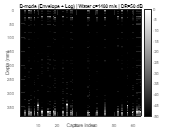

clc; clear; close all;

% =========================
% Settings (edit if needed)
% =========================
pattern = '20260225_*.mat';   % your file pattern
c = 1480;                    % speed of sound in water (m/s)
dynRange_dB = 50;            % display dynamic range (e.g., 40-70)
useTGC = true;               % time gain compensation on/off
tgc_alpha = 1.5;             % strength of TGC (try 0.5 to 3)

% =========================
% Load file list
% =========================
files = dir(pattern);
if isempty(files)
    error('No files found matching: %s', pattern);
end
[~, idx] = sort({files.name});
files = files(idx);

% =========================
% Load first file for timing
% =========================
d0 = load(files(1).name);
if ~isfield(d0,'A') || ~isfield(d0,'Tstart') || ~isfield(d0,'Tinterval')
    error('Expected A, Tstart, Tinterval in %s', files(1).name);
end

A0 = d0.A(:);
N  = length(A0);
t  = d0.Tstart + (0:N-1)*d0.Tinterval;   % seconds (can be negative pre-trigger)

K = numel(files);
B = zeros(N, K, 'single');

% =========================
% Load all A-scans
% =========================
for k = 1:K
    d = load(files(k).name);
    a = d.A(:);

    % handle length mismatch by trunc/pad
    if length(a) ~= N
        warning('Length mismatch in %s (got %d, expected %d). Trunc/pad applied.', ...
            files(k).name, length(a), N);
        aa = zeros(N,1,'single');
        nmin = min(N, length(a));
        aa(1:nmin) = single(a(1:nmin));
        a = aa;
    end

    B(:,k) = single(a);
end

% =========================
% Crop pre-trigger (t < 0)
% =========================
t = t(:);
valid = (t >= 0);
t = t(valid);
B = B(valid,:);

% =========================
% Envelope detection (Hilbert)
% =========================
env = abs(hilbert(double(B)));     % N x K
env = env / max(env(:) + eps);     % normalize (avoid divide-by-zero)

% =========================
% Optional TGC (boost deeper echoes)
% =========================
if useTGC
    % Simple exponential gain vs time (t in seconds)
    g = exp(tgc_alpha * (t / max(t)));    % 1..exp(alpha)
    env = env .* g;                       % apply to each column
    env = env / max(env(:) + eps);        % renormalize
end

% =========================
% Log compression (dB)
% =========================
env_db = 20*log10(env + 1e-12);    % avoid -Inf

% =========================
% Convert time -> depth (mm)
% depth = (c * t / 2)  [meters]
% =========================
depth_mm = (c * t / 2) * 1000;

% =========================
% Display B-mode style image
% =========================
figure;
imagesc(1:K, depth_mm, env_db);
set(gca,'YDir','reverse');         % depth increases downward
colormap(gray);
caxis([-dynRange_dB 0]);           % show [-dynRange, 0] dB
colorbar;

xlabel('Capture Index');
ylabel('Depth (mm)');
title(sprintf('B-mode (Envelope + Log) | Water c=%g m/s | DR=%d dB', c, dynRange_dB));

exportgraphics(gcf, 'Bmode_Water.png', 'Resolution', 300);